Jordan Grotz

2/21/2023

Capsule Robot Path Planning

First we must understand the scale of the provided image so we properly set the scale of the robot. The top opening is 17.1mm. We can determine pixel width by finding the pixel width of that same opening. The points designated were (832,171) and (680,154).

Next we want to properly store the lung map for easy searching. Currently, it is an RGB file, but we can binarize it to make it a series of ones and zeros. 1 is an obstacle, and 0 is an open space

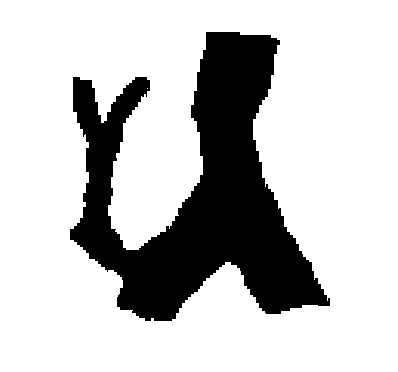

clear all 
clc

lung = imread("939-Oblique.png");
image_size = size(lung);
x_dim = image_size(1);
y_dim = image_size(2);
binary_image = lung(:,:,1) < 1;
%crop image to reduce computation times
final_field = binary_image(122:764,354:977,:);
imshow(final_field);

pixel_size = 17.1/(832-680); %mm


Capsule Size

10mm length by 5mm diameter represented as a 10x5mm rectangle as a 2d projection. The capsule can move in the x, y and rotate around its center. Becuase of symmetry this would mean 180 degrees of rotation could describe all. The approximate pixel size is 90x44. We can create a point cloud of dimensions 9x5, which contains a general collision map for the capsule.

capsule_length = round(10/pixel_size)+1;
capsule_height = round(5/pixel_size);
capsule_points = zeros(5,11,2);
x_max = capsule_length/2

x_max =     45

y_max = capsule_height/2

y_max =     22

x_array = linspace(-x_max,x_max,11);
y_array = linspace(-y_max,y_max,5);
for i = 1:5
    capsule_points(i,:,2) = y_array(i);
    capsule_points(i,:,1) = x_array;
end